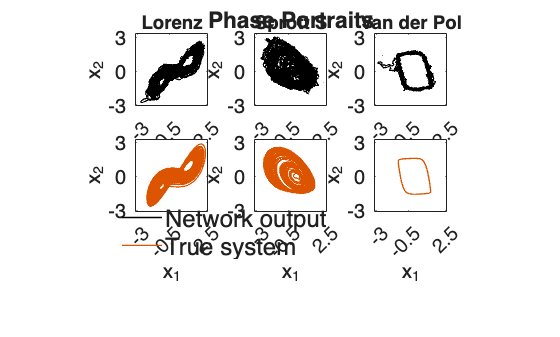

Exported publication PNG: /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_figures/dynamics_phase_portraits.png


%% Network Output vs True System — Publication Examples
% Fig 1: Phase portraits (x1 vs x2; READ and TRUE side-by-side)
% Fig 2: Poincare sections (x1 vs x2) and return maps (x3) in one figure
% Fig 3: Time-series overlays (x1 only; TRUE over network output)
% The newest timestamped saved test result for each system is used. The
% first saved seed entry and first test initial condition are plotted.
clear; clc; close all; rng(123,'twister');
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

%% ---------------- User parameters ----------------
% Systems to plot: [] = all canonical systems with saved 32k-neuron tests;
% otherwise use task IDs, e.g. {'dynamical_systems_lorenz'}.
task_ids = {};
required_n_hidden = 32000;

% Systems to plot after loading: [] = all; otherwise numeric indices.
sys_indices = [];

% ===== Trajectory window/decimation (applies to Figs 1–2) =====
tstart  = 0;
tfrac   = 1;
stride  = 1;

% ===== Manual layout spacing (controls the whitespace between subplots) =====
hgap = 0.00;           % horizontal gap between subplots
vgap = 0.1;            % vertical gap
left_margin   = 0.04;  right_margin  = 0;
bottom_margin = 0.06;  top_margin    = 0.10;

% ===== Geometry =====
equalAx   = false; % (not used now, but kept for compatibility)

% ===== Font sizes =====
fs_ticks  = 15;
fs_labels = 15;
fs_titles = 14;

% ===== Limits (set independently; [] => auto) =====
pp_main_xlim  = [];
pp_main_ylim  = [];
pp_pad_main_left   = 0.05;  pp_pad_main_right  = 0.05;
pp_pad_main_bottom = 0.05;  pp_pad_main_top    = 0.05;

% Poincare sections (per-plot limits/ticks)
sec_xlim = [];  sec_ylim = [];  sec_pad = 0.05;  sec_pad_min_abs = 1e-3;  sec_max_points=5000;

% Return maps (per-plot limits/ticks)
rm_xlim = [];  rm_ylim = [];  rm_pad = 0.05;  rm_pad_min_abs = 1e-3;  rm_max_points=5000;

% Colours/markers
col_read_line    = [0 0 0];
col_true_line    = [0.8660 0.3290 0.0000];
col_read_scatter = [0 0 0];
col_true_scatter = [0.8660 0.3290 0.0000];
ms_read = 16; ms_true = 16;
alpha_read = 0.60; alpha_true = 0.80;

% Line widths (for figs 1–2)
lw_read = 1;   lw_true = 1;

% Recompute controls
rm_min_prom = 1;
sec_slab_thickness = 0;   % 0 => exact crossings; >0 => thin slab
sec_slab_half = max(0, sec_slab_thickness/2);

% ===== Figure 3 — Time-series overlay controls =====
ts_window_s = 10.0;
ts_stride   = 1;
ts_xlim     = [];
ts_ylim     = [];
ts_pad      = 0.05;

% Publication exports overwrite the prior PNGs from this script.
export_dir = fullfile(repo_root, 'outputs', 'publication_figures');
export_dpi = 500;
if exist(export_dir, 'dir') ~= 7, mkdir(export_dir); end

%% ---------------- Load current saved test data ----------------
% The shared loader chooses the newest saved 32k-neuron analysis per canonical
% system, excluding neuron-sweep results. It does not rerun tests, and
% first_seed_only chooses the first saved seed entry.
load_opts = struct('task_ids', {task_ids}, 'first_seed_only', true, ...
    'deduplicate_systems', true, 'required_n_hidden', required_n_hidden);
loaded = load_saved_dynamics_test_results(load_opts);
RES = saved_test_results_to_publication_res(loaded);
Nsys = numel(RES);
if Nsys == 0
    error('No finite saved closed-loop test trajectories were available for plotting.');
end

%% ---------------- Validate choices ----------------
if isempty(sys_indices)
    sys_indices = 1:Nsys;
else
    sys_indices = sys_indices(:).';
    sys_indices = sys_indices(sys_indices>=1 & sys_indices<=Nsys);
    if isempty(sys_indices), error('sys_indices empty after filtering.'); end
end
tstart    = max(0, min(0.999999, tstart));
tfrac     = max(eps, min(1.0, tfrac));
stride    = max(1, round(stride));
ts_stride = max(1, round(ts_stride));
if isempty(sec_max_points), sec_max_points = 0; end
if isempty(rm_max_points),  rm_max_points  = 0; end

%% Return maps use MATLAB's prominence definition; no fallback is permitted.
rm_min_prom = 1;
if exist('findpeaks','file') ~= 2
    error(['Return maps require MATLAB findpeaks with MinPeakProminence = 1. ', ...
           'Install or enable the Signal Processing Toolbox before running this script.']);
end

%% ---------------- GLOBAL limits for PHASE PORTRAITS (x1 vs x2 only) -------------
pp_main_minx = +inf; pp_main_maxx = -inf; 
pp_main_miny = +inf; pp_main_maxy = -inf;

for si = sys_indices
    Ri = RES(si);
    if Ri.D < 2, continue; end

    T = size(Ri.x_read_scaled, 2);
    if T < 2, continue; end
    i0 = 1 + floor(tstart * (T-1));
    i1 = 1 + floor(min(1, tstart + tfrac) * (T-1));
    idx = i0:stride:i1;
    if numel(idx) < 2
        idx = [i0, min(i1, i0+1)];
    end

    Xr1 = double(Ri.x_read_scaled(1, idx));
    Xr2 = double(Ri.x_read_scaled(2, idx));

    pp_main_minx = min(pp_main_minx, min(Xr1));
    pp_main_maxx = max(pp_main_maxx, max(Xr1));
    pp_main_miny = min(pp_main_miny, min(Xr2));
    pp_main_maxy = max(pp_main_maxy, max(Xr2));
end

% MAIN padded global limits
dxg = max(pp_main_maxx - pp_main_minx, eps);
dyg = max(pp_main_maxy - pp_main_miny, eps);
if isempty(pp_main_xlim)
    pp_global_xlim = [pp_main_minx - pp_pad_main_left*dxg, pp_main_maxx + pp_pad_main_right*dxg];
else
    pp_global_xlim = pp_main_xlim;
end
if isempty(pp_main_ylim)
    pp_global_ylim = [pp_main_miny - pp_pad_main_bottom*dyg, pp_main_maxy + pp_pad_main_top*dyg];
else
    pp_global_ylim = pp_main_ylim;
end

% 3 ticks & uniform labels across ALL phase portraits (main)
[pp_xticks, pp_xticklabels] = threeTicksHalf(pp_global_xlim);
[pp_yticks, pp_yticklabels] = threeTicksHalf(pp_global_ylim);

%% ======================= FIGURE 1: PHASE PORTRAITS x1 vs x2 =======================
% Transposed layout: rows = {READ, TRUE}, columns = systems.
pp_sys = sys_indices(arrayfun(@(i) RES(i).D >= 2, sys_indices));
PP_rows = 2;                         % Row 1: READ, Row 2: TRUE
PP_cols = numel(pp_sys);             % One column per system
PP_rows_total = PP_rows + 1;         % +1 legend row

if PP_cols > 0
    fig1 = figure; clf(fig1);
    Pos = axesGridPositions(PP_rows_total, PP_cols, ...
                            left_margin, right_margin, bottom_margin, top_margin, ...
                            hgap, vgap, true);
    publication_axes_title(fig1, 'Phase Portraits', fs_titles+3, Pos, 1);

    cIdx = 0;
    for si = pp_sys
        cIdx = cIdx + 1;
        Ri = RES(si);

        T = size(Ri.x_read_scaled, 2);
        if T < 2, continue; end
        i0 = 1 + floor(tstart * (T-1));
        i1 = 1 + floor(min(1, tstart + tfrac) * (T-1));
        idx = i0:stride:i1;
        if numel(idx) < 2
            idx = [i0, min(i1, i0+1)];
        end

        Xr1 = double(Ri.x_read_scaled(1, idx));
        Xr2 = double(Ri.x_read_scaled(2, idx));
        Xt1 = double(Ri.x_true_scaled(1, idx));
        Xt2 = double(Ri.x_true_scaled(2, idx));

        % ---------- Row 1: READ ----------
        axR = axes('Units','normalized','Position',Pos{1,cIdx});
        axR.FontSize = fs_ticks;
        hold(axR,'on'); box(axR,'on');
        setFixedOuter(axR);
        plot(axR, Xr1, Xr2, '-', 'LineWidth', lw_read, 'Color', col_read_line);
        xlim(axR, pp_global_xlim); ylim(axR, pp_global_ylim);
        axR.XTick = pp_xticks; axR.YTick = pp_yticks;
        axR.XTickLabel = pp_xticklabels; axR.YTickLabel = pp_yticklabels;
        xlabel(axR, 'x_1', 'Interpreter','tex','FontSize',fs_labels);
        ylabel(axR, 'x_2', 'Interpreter','tex','FontSize',fs_labels);
        axis(axR,'square');

        % System name only at the top plot in each column
        title(axR, canonicalSystemName(Ri.system_name), ...
              'Interpreter','tex','FontSize',fs_titles);

        % ---------- Row 2: TRUE ----------
        axT = axes('Units','normalized','Position',Pos{2,cIdx});
        axT.FontSize = fs_ticks;
        hold(axT,'on'); box(axT,'on');
        setFixedOuter(axT);
        plot(axT, Xt1, Xt2, '-', 'LineWidth', lw_true, 'Color', col_true_line);
        xlim(axT, pp_global_xlim); ylim(axT, pp_global_ylim);
        axT.XTick = pp_xticks; axT.YTick = pp_yticks;
        axT.XTickLabel = pp_xticklabels; axT.YTickLabel = pp_yticklabels;
        xlabel(axT, 'x_1', 'Interpreter','tex','FontSize',fs_labels);
        ylabel(axT, 'x_2', 'Interpreter','tex','FontSize',fs_labels);
        axis(axT,'square');
        % No title here, so the column title is only on the READ row.
    end

    % Legend tile: bottom-left cell, nudged up slightly
    pL = Pos{PP_rows_total,1}; pL(2) = pL(2) + 0.15; Pos{PP_rows_total,1} = pL;
    axL = axes('Units','normalized','Position',Pos{PP_rows_total,1});
    axL.FontSize = fs_ticks;
    hold(axL,'on'); box(axL,'off'); axis(axL,'off');
    hRproxy = plot(axL, NaN, NaN, '-', 'Color', col_read_line, 'LineWidth', lw_read);
    hTproxy = plot(axL, NaN, NaN, '-', 'Color', col_true_line, 'LineWidth', lw_true);

    legend(axL, [hRproxy, hTproxy], {"Network output","True system"}, ...
           'Box','off', 'Location','southwest','FontSize',fs_labels+3);
    export_publication_png(fig1, export_dir, 'dynamics_phase_portraits.png', export_dpi);
end

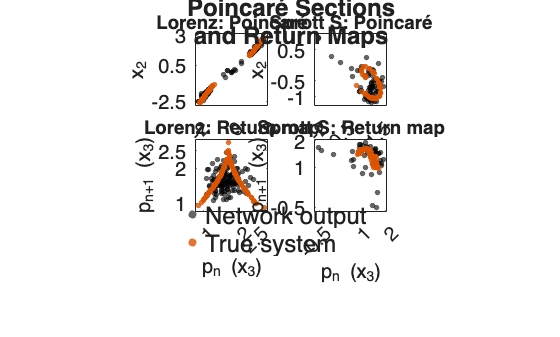

Exported publication PNG: /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_figures/dynamics_poincare_and_return_maps.png



%% ========== FIGURE 2: POINCARÉ SECTIONS (x1 vs x2) + RETURN MAPS (x3) ==========
% Only systems with D >= 3
sec_rm_sys = sys_indices(arrayfun(@(i) RES(i).D >= 3, sys_indices));
SEC_RM_cols = numel(sec_rm_sys);
Nrows_main  = 2;                 % Row 1: Poincare x1-x2; Row 2: return map x3
SEC_RM_rows_total = Nrows_main + 1;  % +1 legend row

if SEC_RM_cols > 0
    fig2 = figure; clf(fig2);
    Pos = axesGridPositions(SEC_RM_rows_total, SEC_RM_cols, left_margin, right_margin, bottom_margin, top_margin, hgap, vgap, true);
    publication_axes_title(fig2, 'Poincaré Sections and Return Maps', fs_titles+4, Pos, 1);

    for cidx = 1:SEC_RM_cols
        si = sec_rm_sys(cidx);
        Ri = RES(si);
        D  = Ri.D;

        T = size(Ri.x_read_scaled, 2);
        if T < 2
            continue;
        end
        i0 = 1 + floor(tstart * (T-1));
        i1 = 1 + floor(min(1, tstart + tfrac) * (T-1));
        idx = i0:stride:i1;
        if numel(idx) < 2
            idx = [i0, min(i1, i0+1)];
        end

        Xr = double(Ri.x_read_scaled(:, idx));
        Xt = double(Ri.x_true_scaled(:, idx));

        %% ---- Poincare section: x1 vs x2, section in x3 ----
        Pr_sec = zeros(0,2);
        Pt_sec = zeros(0,2);
        if D >= 3 && isfield(Ri,'sections') && ~isempty(Ri.sections)
            secs = Ri.sections;
            sdim_list = [secs.sdim];
            idx3 = find(sdim_list == 3, 1);
            if ~isempty(idx3)
                sdim = 3;
                slev = double(secs(idx3).level);
                sdir = double(secs(idx3).dir);

                % READ intersections
                x0R = Xr(sdim,1:end-1); x1R = Xr(sdim,2:end);
                d0R = x0R - slev;       d1R = x1R - slev;
                crossesR = (d0R<=0 & d1R>=0) | (d0R>=0 & d1R<=0);
                inSlabR  = (abs(d0R)<=sec_slab_half) | (abs(d1R)<=sec_slab_half);
                dirOK_R  = (sdir>0).*(x1R>x0R) + (sdir<0).*(x1R<x0R);
                dirOK_R  = logical(dirOK_R);
                maskR = (sec_slab_half>0) .* ((crossesR | inSlabR) & (x1R~=x0R) & dirOK_R) ...
                      + (sec_slab_half==0).* (crossesR & (x1R~=x0R) & dirOK_R);
                maskR = logical(maskR);
                posR = find(maskR);
                alphaR = (slev - x0R(maskR))./(x1R(maskR) - x0R(maskR));
                alphaR = max(0,min(1,alphaR));

                % TRUE intersections
                x0T = Xt(sdim,1:end-1); x1T = Xt(sdim,2:end);
                d0T = x0T - slev;       d1T = x1T - slev;
                crossesT = (d0T<=0 & d1T>=0) | (d0T>=0 & d1T<=0);
                inSlabT  = (abs(d0T)<=sec_slab_half) | (abs(d1T)<=sec_slab_half);
                dirOK_T  = (sdir>0).*(x1T>x0T) + (sdir<0).*(x1T<x0T);
                dirOK_T  = logical(dirOK_T);
                maskT = (sec_slab_half>0) .* ((crossesT | inSlabT) & (x1T~=x0T) & dirOK_T) ...
                      + (sec_slab_half==0).* (crossesT & (x1T~=x0T) & dirOK_T);
                maskT = logical(maskT);
                posT = find(maskT);
                alphaT = (slev - x0T(maskT))./(x1T(maskT) - x0T(maskT));
                alphaT = max(0,min(1,alphaT));

                a = 1; b = 2;  % Poincare panel is always x1 vs x2

                % READ: coordinates x1,x2 at crossings
                if ~isempty(posR)
                    Y0a = Xr(a, posR); Y1a = Xr(a, posR+1);
                    Y0b = Xr(b, posR); Y1b = Xr(b, posR+1);
                    Pra = (Y0a + (Y1a - Y0a).*alphaR).';
                    Prb = (Y0b + (Y1b - Y0b).*alphaR).';
                    Pr_sec = [Pra, Prb];
                end

                % TRUE: coordinates x1,x2 at crossings
                if ~isempty(posT)
                    Y0a = Xt(a, posT); Y1a = Xt(a, posT+1);
                    Y0b = Xt(b, posT); Y1b = Xt(b, posT+1);
                    Pta = (Y0a + (Y1a - Y0a).*alphaT).';
                    Ptb = (Y0b + (Y1b - Y0b).*alphaT).';
                    Pt_sec = [Pta, Ptb];
                end

                if sec_max_points>0
                    Pr_sec = takeFirstN(Pr_sec, sec_max_points);
                    Pt_sec = takeFirstN(Pt_sec, sec_max_points);
                end
            end
        end

        % Plot Poincare
        axP = axes('Units','normalized','Position',Pos{1,cidx});
        axP.FontSize = fs_ticks;
        setFixedOuter(axP); hold(axP,'on'); box(axP,'on');
        if ~isempty(Pr_sec)
            scatter(axP, Pr_sec(:,1), Pr_sec(:,2), ms_read, ...
                'MarkerFaceColor', col_read_scatter, 'MarkerEdgeColor','none', ...
                'MarkerFaceAlpha', alpha_read);
        end
        if ~isempty(Pt_sec)
            scatter(axP, Pt_sec(:,1), Pt_sec(:,2), ms_true, ...
                'MarkerFaceColor', col_true_scatter, 'MarkerEdgeColor','none', ...
                'MarkerFaceAlpha', alpha_true);
        end

        xx = [Pr_sec(:,1); Pt_sec(:,1)]; yy = [Pr_sec(:,2); Pt_sec(:,2)];
        if isempty(xx), xx = [0; 1]; end
        if isempty(yy), yy = [0; 1]; end
        xmin = min(xx,[],'omitnan'); xmax = max(xx,[],'omitnan');
        ymin = min(yy,[],'omitnan'); ymax = max(yy,[],'omitnan');
        dx = max(xmax - xmin, eps); dy = max(ymax - ymin, eps);
        padx = max(sec_pad*dx, sec_pad_min_abs); pady = max(sec_pad*dy, sec_pad_min_abs);
        if isempty(sec_xlim), xl = [xmin - padx, xmax + padx]; else, xl = sec_xlim; end
        if isempty(sec_ylim), yl = [ymin - pady, ymax + pady]; else, yl = sec_ylim; end
        xlim(axP, xl); ylim(axP, yl);
        [xtk, xtl] = threeTicksHalf(xl); [ytk, ytl] = threeTicksHalf(yl);
        axP.XTick = xtk; axP.YTick = ytk; axP.XTickLabel = xtl; axP.YTickLabel = ytl;
        xlabel(axP, 'x_1', 'Interpreter','tex','FontSize',fs_labels);
        ylabel(axP, 'x_2', 'Interpreter','tex','FontSize',fs_labels);
        axis(axP,'square');
        title(axP, sprintf('%s: Poincaré', canonicalSystemName(Ri.system_name)), 'Interpreter','tex','FontSize',fs_titles);

        %% ---- Return map for x3 ----
        Pr_rm = zeros(0,2);
        Pt_rm = zeros(0,2);
        if D >= 3
            xr = Xr(3,:); xt = Xt(3,:);
            try
                [pR, ~] = findpeaks(xr, 'MinPeakProminence', rm_min_prom);
                [pT, ~] = findpeaks(xt, 'MinPeakProminence', rm_min_prom);
            catch ME
                error('plot_phase_portraits_return_maps_poincare_sections:findpeaksFailed', ...
                    'Return maps require findpeaks with MinPeakProminence = 1: %s', ME.message);
            end
            if numel(pR) >= 2
                Pr_rm = [pR(1:end-1).', pR(2:end).'];
            end
            if numel(pT) >= 2
                Pt_rm = [pT(1:end-1).', pT(2:end).'];
            end
            if rm_max_points>0
                Pr_rm = takeFirstN(Pr_rm, rm_max_points);
                Pt_rm = takeFirstN(Pt_rm, rm_max_points);
            end
        end

        % Plot return map
        axR = axes('Units','normalized','Position',Pos{2,cidx});
        axR.FontSize = fs_ticks;
        setFixedOuter(axR); hold(axR,'on'); box(axR,'on');
        if ~isempty(Pr_rm)
            scatter(axR, Pr_rm(:,1), Pr_rm(:,2), ms_read, ...
                'MarkerFaceColor', col_read_scatter, 'MarkerEdgeColor','none', ...
                'MarkerFaceAlpha', alpha_read);
        end
        if ~isempty(Pt_rm)
            scatter(axR, Pt_rm(:,1), Pt_rm(:,2), ms_true, ...
                'MarkerFaceColor', col_true_scatter, 'MarkerEdgeColor','none', ...
                'MarkerFaceAlpha', alpha_true);
        end

        xx = [Pr_rm(:,1); Pt_rm(:,1)]; yy = [Pr_rm(:,2); Pt_rm(:,2)];
        if isempty(xx), xx = [0; 1]; end
        if isempty(yy), yy = [0; 1]; end
        xmin = min(xx,[],'omitnan'); xmax = max(xx,[],'omitnan');
        ymin = min(yy,[],'omitnan'); ymax = max(yy,[],'omitnan');
        dx = max(xmax - xmin, eps); dy = max(ymax - ymin, eps);
        padx = max(rm_pad*dx, rm_pad_min_abs); pady = max(rm_pad*dy, rm_pad_min_abs);
        if isempty(rm_xlim), xl = [xmin - padx, xmax + padx]; else, xl = rm_xlim; end
        if isempty(rm_ylim), yl = [ymin - pady, ymax + pady]; else, yl = rm_ylim; end
        xlim(axR, xl); ylim(axR, yl);
        [xtk, xtl] = threeTicksHalf(xl); [ytk, ytl] = threeTicksHalf(yl);
        axR.XTick = xtk; axR.YTick = ytk; axR.XTickLabel = xtl; axR.YTickLabel = ytl;
        xlabel(axR, 'p_n (x_3)', 'Interpreter','tex','FontSize',fs_labels);
        ylabel(axR, 'p_{n+1} (x_3)', 'Interpreter','tex','FontSize',fs_labels);
        axis(axR,'square');
        title(axR, sprintf('%s: Return map', canonicalSystemName(Ri.system_name)), 'Interpreter','tex','FontSize',fs_titles);
    end

    % Legend tile, nudged up
    pL = Pos{SEC_RM_rows_total,1}; pL(2) = pL(2) + 0.16; Pos{SEC_RM_rows_total,1} = pL;
    axL = axes('Units','normalized','Position',Pos{SEC_RM_rows_total,1});
    axL.FontSize = fs_ticks;
    hold(axL,'on'); box(axL,'off'); axis(axL,'off');
    hRproxy = scatter(axL, NaN, NaN, ms_read, ...
        'MarkerFaceColor', col_read_scatter, 'MarkerEdgeColor','none', ...
        'MarkerFaceAlpha', alpha_read);
    hTproxy = scatter(axL, NaN, NaN, ms_true, ...
        'MarkerFaceColor', col_true_scatter, 'MarkerEdgeColor','none', ...
        'MarkerFaceAlpha', alpha_true);
    legend(axL, [hRproxy, hTproxy], {"Network output","True system"}, ...

           'Box','off', 'Location','southwest','FontSize',fs_labels+3);
    export_publication_png(fig2, export_dir, 'dynamics_poincare_and_return_maps.png', export_dpi);
end


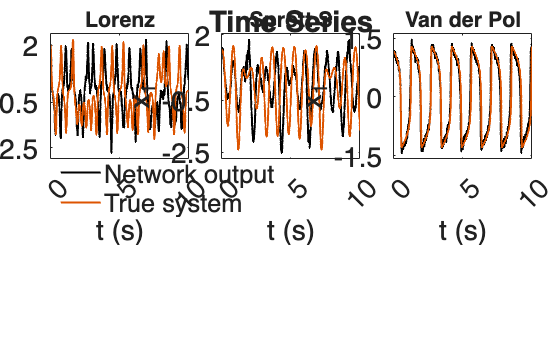

Exported publication PNG: /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_figures/dynamics_time_series.png


%% ===================== FIGURE 3: TIME-SERIES OVERLAYS (x1 only) ==================
% Override line widths for time series
lw_read = 1.5;
lw_true = 1.5;

ts_sys = sys_indices;
TS_cols = numel(ts_sys);
TS_rows = 1;              % only x1
TS_rows_total = TS_rows + 1;

if TS_rows > 0 && TS_cols > 0
    fig3 = figure; clf(fig3);
    % time series are NOT square — rectangular grid
    Pos = axesGridPositions(TS_rows_total, TS_cols, left_margin+0.05, right_margin+0.05, bottom_margin, top_margin, hgap+0.06, vgap, false);
    publication_axes_title(fig3, 'Time Series', fs_titles+8, Pos, 1);

    cidx = 0;
    for si = ts_sys
        cidx = cidx + 1;
        Ri = RES(si);

        % Main-time vector; if missing, reconstruct from dt and length
        t_all = double(Ri.t(:));
        if isempty(t_all)
            dt_loc = double(Ri.dt);
            Tsteps = size(Ri.x_read_scaled,2);
            t_all = (0:Tsteps-1).' * dt_loc;
        end

        t0   = t_all(1);
        tmax = min(t0 + ts_window_s, t_all(end));
        idx  = find(t_all >= t0 & t_all <= tmax);
        idx  = idx(1:ts_stride:end);

        Tr = t_all(idx);
        if isempty(Tr)
            continue;
        end
        Xr = double(Ri.x_read_scaled(:, idx));
        Xt = double(Ri.x_true_scaled(:, idx));

        dim = 1;  % only first dimension

        ax = axes('Units','normalized','Position',Pos{1,cidx});
        ax.FontSize = fs_ticks+6;
        setFixedOuter(ax); hold(ax,'on'); box(ax,'on');
        plot(ax, Tr, Xr(dim,:), '-', 'LineWidth', lw_read, 'Color', col_read_line);
        plot(ax, Tr, Xt(dim,:), '-', 'LineWidth', lw_true, 'Color', col_true_line);

        % y-limits
        if isempty(ts_ylim)
            yy = [Xr(dim,:), Xt(dim,:)];
            ymin = min(yy); ymax = max(yy); dy = max(ymax - ymin, eps);
            yl = [ymin - ts_pad*dy, ymax + ts_pad*dy];
        else
            yl = ts_ylim;
        end
        ylim(ax, yl);

        % x-limits
        if isempty(ts_xlim)
            xl = [t0, tmax];
        else
            xl = ts_xlim;
        end
        xlim(ax, xl);

        xlabel(ax, 't (s)', 'Interpreter','tex','FontSize',fs_labels+6);
        ylabel(ax, 'x_1', 'Interpreter','tex','FontSize',fs_labels+6);

        [xtk, xtl] = threeTicksHalf(xl); [ytk, ytl] = threeTicksHalf(yl);
        ax.XTick = xtk; ax.YTick = ytk; ax.XTickLabel = xtl; ax.YTickLabel = ytl;

        title(ax, canonicalSystemName(Ri.system_name), 'Interpreter','tex','FontSize',fs_titles+2);
        % (time-series are intentionally NOT square)
    end

    % Legend tile: bottom-left cell, nudged up
    pL = Pos{TS_rows_total,1}; pL(2) = pL(2) + 0.27; Pos{TS_rows_total,1} = pL;
    axL = axes('Units','normalized','Position',Pos{TS_rows_total,1});
    axL.FontSize = fs_ticks;
    hold(axL,'on'); box(axL,'off'); axis(axL,'off');
    hRproxy = plot(axL, NaN, NaN, '-', 'Color', col_read_line, 'LineWidth', lw_read);
    hTproxy = plot(axL, NaN, NaN, '-', 'Color', col_true_line, 'LineWidth', lw_true);
    legend(axL, [hRproxy, hTproxy], {"Network output","True system"}, ...
           'Box','off', 'Location','southwest','FontSize',fs_labels+4);

    export_publication_png(fig3, export_dir, 'dynamics_time_series.png', export_dpi);
end

%% ---------------- Helpers ----------------
function tf = isVanDerPol(sysname)
    nm = lower(string(sysname));
    nm = replace(nm, [" ","-","_"], "");
    tf = contains(nm, "vanderpol") || contains(nm, "vdp") || ...
         contains(nm,"vander pol") || contains(nm,"van der pol");
end

function nice = canonicalSystemName(sysname)
    s = lower(strtrim(char(sysname)));
    s = regexprep(s,'[\s_\-]+',' ');
    if contains(s,'vander pol') || contains(s,'van der pol') || ...
       contains(s,'vanderpol') || contains(s,'vdp')
        nice = 'Van der Pol';
    elseif contains(s,'lorenz')
        nice = 'Lorenz';
    elseif contains(s,'sprotts') || contains(s,'sprott s') || ...
           contains(s,'sprott-s') || contains(s,'sprott s.')
        nice = 'Sprott S';
    else
        words = regexp(s,'\s+','split');
        for ii=1:numel(words)
            w = words{ii};
            if ~isempty(w)
                words{ii} = [upper(w(1)) lower(w(2:end))];
            end
        end
        nice = strjoin(words,' ');
    end
end

function [ticks, labels] = threeTicksHalf(xlimv)
    L = xlimv(1); U = xlimv(2);
    if ~(isfinite(L) && isfinite(U)) || U <= L
        L = 0; U = 1;
    end
    a = ceilToHalf(L);   % round up to nearest .0/.5
    b = floorToHalf(U);  % round down to nearest .0/.5
    if b - a < 1e-12
        c = roundToHalf((L+U)/2);
        ticks = [c-0.5, c, c+0.5];
    else
        m = roundToHalf((a + b)/2);
        if m <= a, m = a + 0.5; end
        if b <= m, b = m + 0.5; end
        ticks = [a, m, b];
    end
    labels = arrayfun(@(v) formatHalf(v), ticks, 'UniformOutput', false);
end

function y = roundToHalf(x), y = round(2*x)/2; end
function y = ceilToHalf(x),  y = ceil(2*x)/2;  end
function y = floorToHalf(x), y = floor(2*x)/2; end
function s = formatHalf(v)
    if abs(v - round(v)) < 1e-12
        s = sprintf('%.0f', v);
    else
        s = sprintf('%.1f', v);
    end
end

function M = takeFirstN(M, N)
    if isempty(M) || N<=0, return; end
    if size(M,1) > N, M = M(1:N,:); end
end

function setFixedOuter(ax)
% Constrain by INNER position so titles/labels do not change inner plot box size.
    if isprop(ax,'ActivePositionProperty')
        ax.ActivePositionProperty = 'Position';
    end
    if isprop(ax,'PositionConstraint')
        ax.PositionConstraint = 'innerposition';
    end
end

function title_handle = publication_axes_title(fig, title_text, font_size, Pos, row_index)
% Place a title above the axes grid, excluding the visual width of y-labels.
n_cols = size(Pos, 2);
left = Pos{row_index, 1}(1);
right_pos = Pos{row_index, n_cols};
right = right_pos(1) + right_pos(3);
grid_top = max(cellfun(@(p) p(2) + p(4), Pos(row_index, :)));
width = min(0.80, max(0.30, right - left));
height = 0.045;
x = (left + right) / 2 - width / 2;
y = min(0.95, grid_top + 0.015);
title_handle = annotation(fig, 'textbox', [x, y, width, height], ...
    'String', title_text, 'Interpreter', 'tex', 'FontSize', font_size, ...
    'FontWeight', 'bold', 'HorizontalAlignment', 'center', ...
    'VerticalAlignment', 'middle', 'EdgeColor', 'none', 'FitBoxToText', 'off');
end

function export_publication_png(fig, output_dir, filename, dpi)
drawnow;
output_file = fullfile(output_dir, filename);
if exist('exportgraphics', 'file') == 2
    exportgraphics(fig, output_file, 'Resolution', dpi);
else
    print(fig, output_file, '-dpng', sprintf('-r%d', dpi));
end
fprintf('Exported publication PNG: %s%s', output_file, newline);
end

function Pos = axesGridPositions(nRows, nCols, L, R, B, Tm, Hgap, Vgap, forceSquare)
% Build a grid of axes positions (top-to-bottom rows, left-to-right columns).
% If forceSquare==true, tiles are square and tightly packed.
    if nargin<9, forceSquare = true; end
    Pos = cell(nRows, nCols);
    totalW = 1 - L - R - (nCols-1)*Hgap;
    totalH = 1 - Tm - B - (nRows-1)*Vgap;
    if totalW <= 0 || totalH <= 0
        error('Invalid layout margins/gaps resulting in non-positive drawing area.');
    end
    w = totalW / nCols;
    h = totalH / nRows;

    if forceSquare
        side = min(w, h);
        stepX = side + Hgap;  stepY = side + Vgap;
        usedW = nCols*side + (nCols-1)*Hgap;
        usedH = nRows*side + (nRows-1)*Vgap;
        xLeft = L + max(0, (totalW - usedW)/2);
        yTop  = 1 - Tm;  % top edge
        for c = 1:nCols
            x = xLeft + (c-1)*stepX;
            for r = 1:nRows
                y = yTop - r*side - (r-1)*Vgap;
                Pos{r,c} = [x, y, side, side];
            end
        end
    else
        % rectangular tiles filling the drawable box
        for c = 1:nCols
            x = L + (c-1)*(w + Hgap);
            for r = 1:nRows
                y = 1 - Tm - r*h - (r-1)*Vgap;
                Pos{r,c} = [x, y, w, h];
            end
        end
    end
end

function RES = saved_test_results_to_publication_res(loaded)
% Convert the current saved-test schema to the legacy plotting schema while
% retaining the publication figure layout above.
template = struct('D', [], 'x_read_scaled', [], 'x_true_scaled', [], ...
    'system_name', '', 'dt', [], 't', [], 'sections', struct([]));
RES = repmat(template, 1, numel(loaded.seed_results));
keep = 0;
for ii = 1:numel(loaded.seed_results)
    entry = loaded.seed_results(ii);
    [pred, truth] = first_saved_closed_loop_trajectory(entry.test);
    n = min(size(pred, 1), size(truth, 1));
    if n < 2
        warning('plot_phase_portraits_return_maps_poincare_sections:shortTrajectory', ...
            'Skipping saved task %s because its first test trajectory is too short.', entry.task_id);
        continue;
    end
    pred = double(pred(1:n, :));
    truth = double(truth(1:n, :));
    if any(~isfinite(pred(:))) || any(~isfinite(truth(:)))
        warning('plot_phase_portraits_return_maps_poincare_sections:nonfiniteTrajectory', ...
            'Skipping saved task %s because its first test trajectory contains non-finite values.', entry.task_id);
        continue;
    end
    keep = keep + 1;
    RES(keep).D = min(size(pred, 2), size(truth, 2));
    RES(keep).x_read_scaled = pred(:, 1:RES(keep).D).';
    RES(keep).x_true_scaled = truth(:, 1:RES(keep).D).';
    RES(keep).system_name = get_option_field(entry.options, 'system_name', entry.task_id);
    RES(keep).dt = double(get_option_field(entry.options, 'dt', 1));
    RES(keep).t = (0:n-1).' .* RES(keep).dt;
    if RES(keep).D >= 3
        z = RES(keep).x_true_scaled(3, :);
        z = z(isfinite(z));
        if isempty(z), level = 0; else, level = median(z); end
        RES(keep).sections = struct('sdim', 3, 'level', level, 'dir', 1);
    end
end
RES = RES(1:keep);
end

function [pred, truth] = first_saved_closed_loop_trajectory(test)
if isfield(test, 'closed_loop') && isstruct(test.closed_loop)
    test = test.closed_loop;
end
if isfield(test, 'pred_norm_by_ic') && isfield(test, 'true_norm_by_ic')
    pred = first_cell_or_value(test.pred_norm_by_ic);
    truth = first_cell_or_value(test.true_norm_by_ic);
elseif isfield(test, 'pred_norm') && isfield(test, 'true_norm')
    pred = test.pred_norm;
    truth = test.true_norm;
else
    error('plot_phase_portraits_return_maps_poincare_sections:missingTrajectory', ...
        'Saved test entry does not contain closed-loop pred_norm/true_norm trajectories.');
end
end

function value = first_cell_or_value(value)
if iscell(value)
    if isempty(value)
        value = zeros(0, 0);
    else
        value = value{1};
    end
end
end

function value = get_option_field(options, name, default_value)
if isstruct(options) && isfield(options, name) && ~isempty(options.(name))
    value = options.(name);
else
    value = default_value;
end
end
